# 02 | Select and inspect 60-s segments 

INPUT: one continuous preprocessed record, or a supplied 60-s example. OUTPUT: QC preview + candidate MAT; accepted MAT only after manual decision. This retains the original inspect -> select interval -> inspect -> save logic. Never concatenate separated clean intervals into a false continuous record.

## 1. Paths, input and manual selection 

codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir = gate_output_dir(codeDir,'02_segments');
useStep01Output = false;          % true: inspect the output from step 01.
inputFile = fullfile(codeDir,'example_inputs','Rat07_130Hz_OL_Pre_seg010.mat');
if useStep01Output
    inputFile = fullfile(gate_output_dir(codeDir,'01_preprocess'),'preprocessed_example.mat');
end
segmentSeconds = 60;
selectedStartSeconds = 0;         % One start time, measured in the input file.
qcAccepted = false;               % Change only after inspecting this segment.
qcNote = 'Pending manual inspection';

## 2. Load and validate the selected interval

[data,fs] = gate_load_lfp(inputFile);
recordSeconds = numel(data)/fs;
assert(isscalar(selectedStartSeconds) && selectedStartSeconds>=0);
assert(selectedStartSeconds+segmentSeconds<=recordSeconds+1e-10, ...
    'Selected interval exceeds the available record.');
firstSample = round(selectedStartSeconds*fs)+1;
nSamples = round(segmentSeconds*fs);
lastSample = firstSample+nSamples-1;
data1 = data(firstSample:lastSample);
segmentTime = (0:nSamples-1)'/fs;

## 3. Calculate a PSD for visual QC

Explicit periodic Hann avoids the same-name hann function conflict. This QC PSD does not replace notebook 03's explicitly detrended Welch PSD.

nWindow = round(2*fs);
window = gate_hann(nWindow,'periodic');
[pwr,freq] = pwelch(data1,window,round(fs),nWindow,fs);

## 4. Calculate a spectrogram 

One-second Hamming windows and 90% overlap follow the original QC display. This display has different resolution from the 2-s analysis Welch PSD.

specLength = round(fs);
specWindow = 0.54-0.46*cos(2*pi*(0:specLength-1)'/(specLength-1));
[~,specF,specT,specP] = spectrogram(data1,specWindow,round(0.9*fs),[],fs);
displayBand = specF>=2 & specF<=90;
displayDb = 10*log10(max(specP(displayBand,:),realmin));

## 5. Inspect waveform, PSD and time-frequency structure 

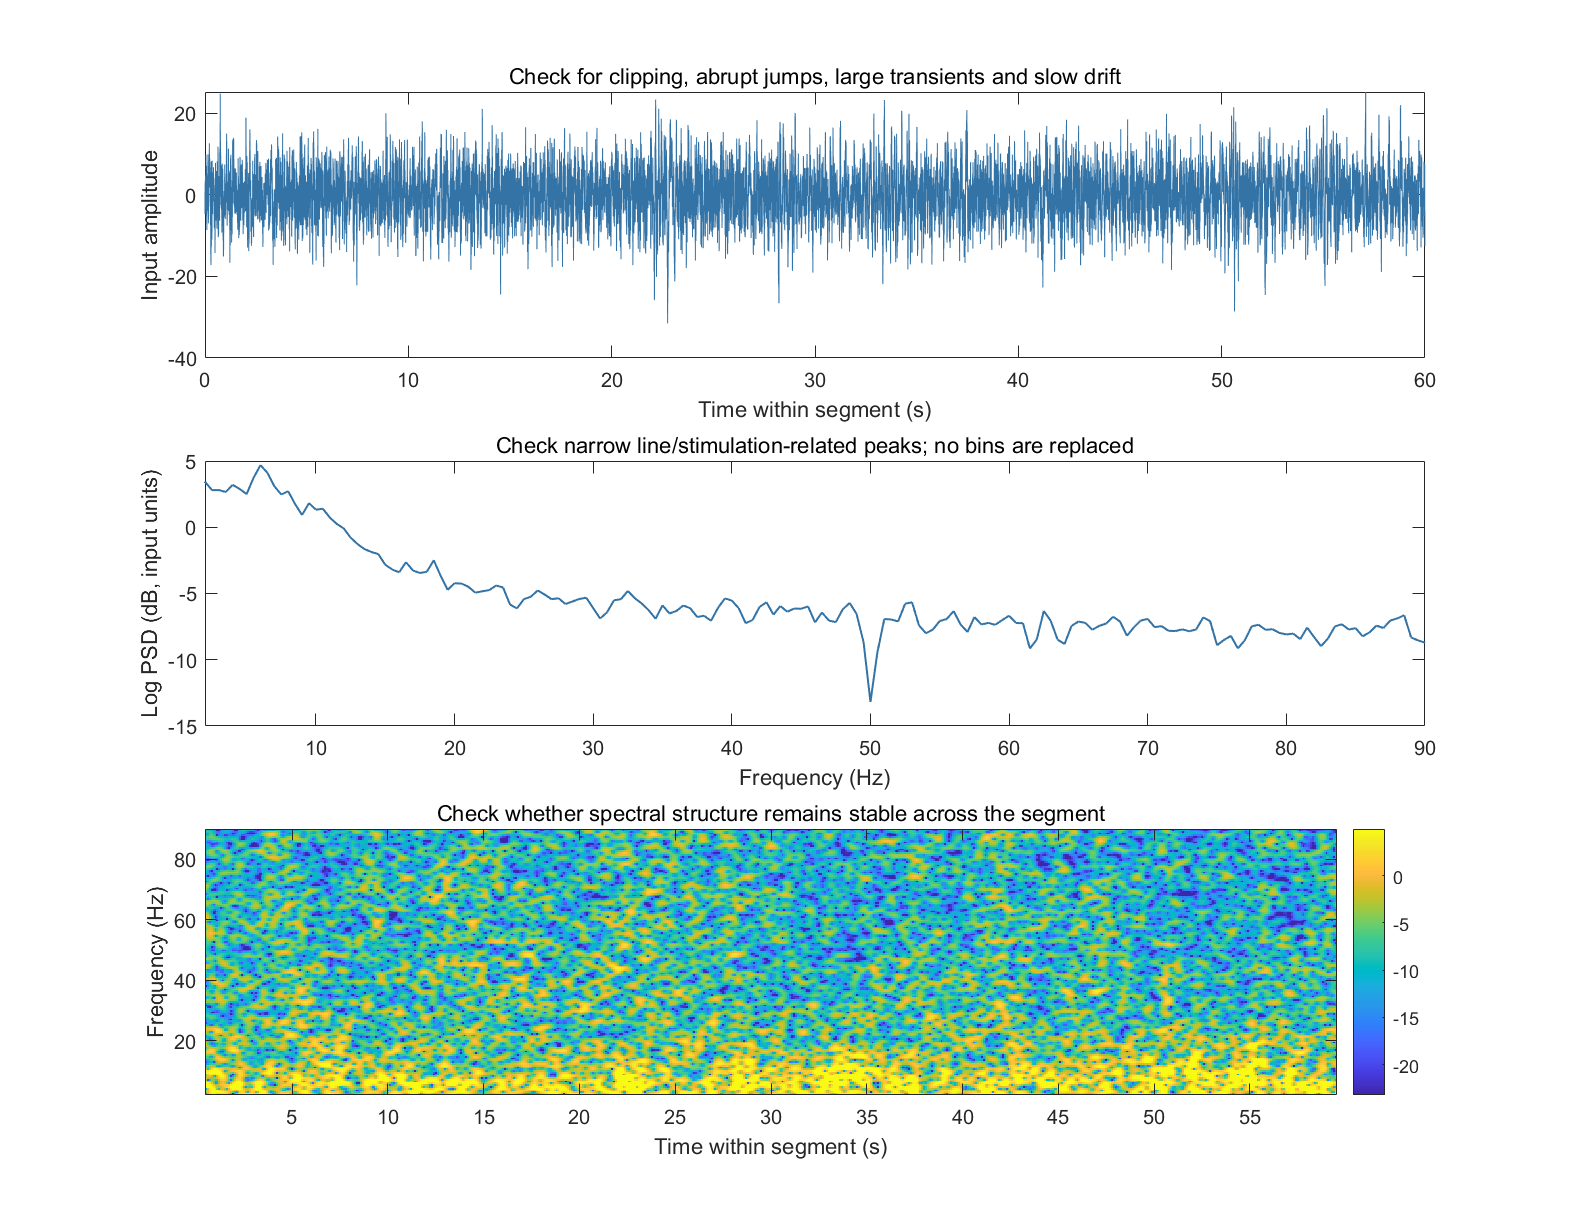

fig = figure('Color','w','Position',[100 100 1050 820]);
subplot(3,1,1);
plot(segmentTime,data1,'Color',[0.2 0.45 0.65],'LineWidth',0.5);
xlim([0 segmentSeconds]); xlabel('Time within segment (s)'); ylabel('Input amplitude');
title('Check for clipping, abrupt jumps, large transients and slow drift');
subplot(3,1,2);
plot(freq,10*log10(max(pwr,realmin)),'Color',[0.2 0.45 0.65],'LineWidth',1);
xlim([2 90]); xlabel('Frequency (Hz)'); ylabel('Log PSD (dB, input units)');
title('Check narrow line/stimulation-related peaks; no bins are replaced');
subplot(3,1,3);
imagesc(specT,specF(displayBand),displayDb); axis xy; ylim([2 90]);
% Color limits use the 2nd/98th percentiles within the displayed band, so
% attenuated frequencies outside 2-90 Hz do not flatten the color contrast.
% This changes colors only; all original signal and spectral values are kept.
orderedPower = sort(displayDb(:));
lowerIndex = max(1,ceil(0.02*numel(orderedPower)));
upperIndex = min(numel(orderedPower),ceil(0.98*numel(orderedPower)));
if orderedPower(upperIndex)>orderedPower(lowerIndex)
    caxis([orderedPower(lowerIndex) orderedPower(upperIndex)]);
end
xlabel('Time within segment (s)'); ylabel('Frequency (Hz)'); colorbar;
title('Check whether spectral structure remains stable across the segment');
exportgraphics(fig,fullfile(outDir,'segment_QC.png'),'Resolution',180);

## 6. Record the decision and save 

A generated preview is not automatic artifact certification. Re-run after setting qcAccepted=true and adding a meaningful qcNote.

[~,sourceName,sourceExtension] = fileparts(inputFile);
sourceName = [sourceName sourceExtension];
selection = struct('source_file',sourceName,'start_seconds',selectedStartSeconds, ...
    'duration_seconds',segmentSeconds,'first_sample',firstSample,'last_sample',lastSample);
if qcAccepted
    outputName = 'accepted_segment.mat';
else
    outputName = 'candidate_segment.mat';
end
save(fullfile(outDir,outputName),'data1','fs','freq','pwr','qcAccepted','qcNote','selection');
decision = table(string(sourceName),selectedStartSeconds,segmentSeconds,qcAccepted,string(qcNote), ...
    'VariableNames',{'SourceFile','Start_s','Duration_s','Accepted','QCNote'});
writetable(decision,fullfile(outDir,'segment_QC_decision.csv'));
disp(decision);

              SourceFile               Start_s    Duration_s    Accepted              QCNote           
    _______________________________    _______    __________    ________    ___________________________

    "Rat07_130Hz_OL_Pre_seg010.mat"       0           60         false      "Pending manual inspection"



% Notebook 03 defaults to the supplied manifest. To analyze this selection,
% switch its input_mode to accepted_step02; it rejects an unaccepted candidate.